# AlexNet

%                Downloading the AlexNet support package
% 
% Type " alexnet" in the command window. 
%    If the add-on is NOT installed an error message will appear. Follow that
%    prompt to install the add-on.

%    If the add-on is installed the command window will dispay
%    "SeriesNetwork" with properties

%                Load Data
imageFolder= '\\client\c$\Documents\BME 3053C\project\brain_tumor_dataset' % update to the your file location

imageFolder = '\\client\c$\Documents\BME 3053C\project\brain_tumor_dataset'

imds = imageDatastore(imageFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
% Divide the data into training and test sets at 30% and 70% respectively
[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');
% Load the pretrained network
net = alexnet;
layersTransfer = net.Layers(1:end-3);
numClasses = numel(categories(trainingSet.Labels))

numClasses = 2

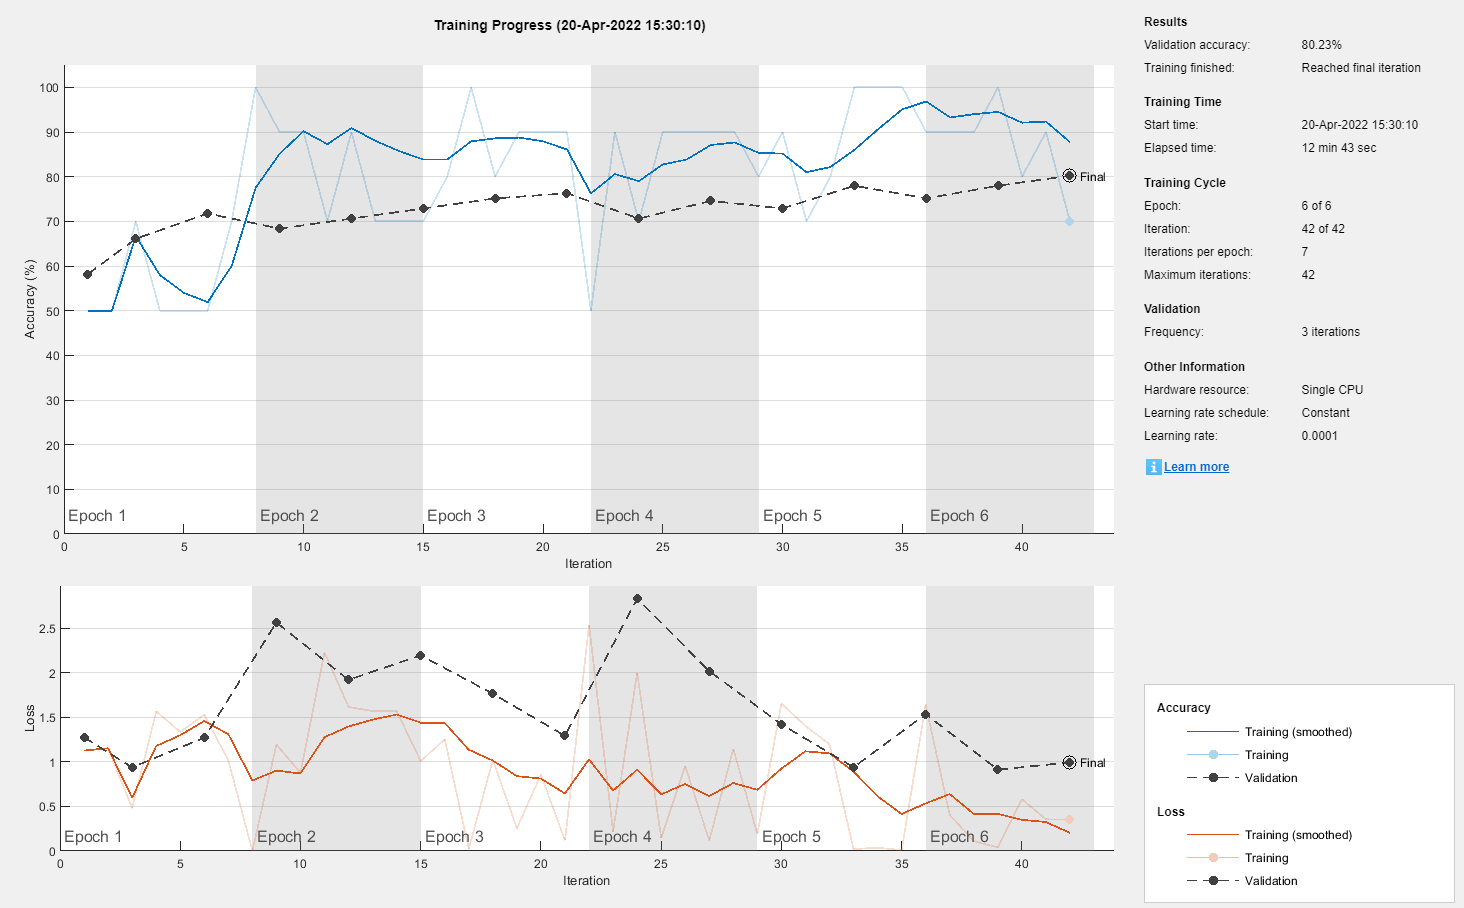

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];
pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing', 'gray2rgb');
augtestSet = augmentedImageDatastore(inputSize(1:2),testSet, 'ColorPreprocessing', 'gray2rgb');
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augtestSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');
netTransfer = trainNetwork(augimdsTrain,layers,options);

[YPred,scores] = classify(netTransfer,augtestSet);
YValidation = testSet.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.8023